Parameters

k = 8

k = 8

## Part a

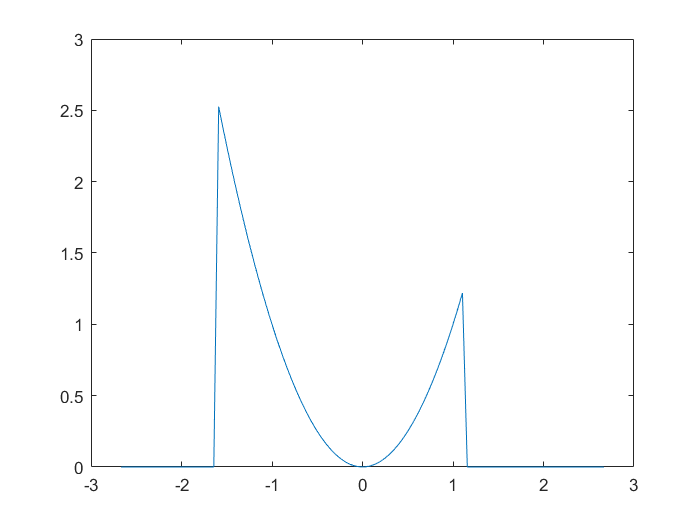

L = k/3*2;
x = linspace(-L/2, L/2);
plot(x, f(x, k));

Fourier coefficients

syms x n
assume(in(n, 'integer') & n > 0)

syms f_sym(x)
f_sym(x) = x^2;

a_0 = int(f_sym(x) * cos(pi*0*x/(L/2)), x, -k/5, k/7)

$$a\_0 = \frac{79872}{42875}$$

a_n = simplify(int(f_sym(x) * cos(pi*n*x/(L/2)), x, -k/5, k/7))

$$a\_n = \begin{array}{l} \frac{8\,\left(\frac{576\,n^{2}\,\pi^{2}\,\sigma_{3}}{25}-128\,\sigma_{3}+\frac{384\,\pi \,n\,\cos\left(\frac{3\,\pi \,n}{5}\right)}{5}\right)}{\sigma_{1}}+\frac{8\,\left(\frac{576\,n^{2}\,\pi^{2}\,\sigma_{2}}{49}-128\,\sigma_{2}+\frac{384\,\pi \,n\,\cos\left(\frac{3\,\pi \,n}{7}\right)}{7}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=27\,n^{3}\,\pi^{3}\\ \sigma_{2}=\sin\left(\frac{3\,\pi \,n}{7}\right)\\ \sigma_{3}=\sin\left(\frac{3\,\pi \,n}{5}\right) \end{array}$$

b_n = simplify(int(f_sym(x) * sin(pi*n*x/(L/2)), x, -k/5, k/7))

$$b\_n = \begin{array}{l} -\frac{\frac{1024\,\sigma_{2}}{27}-\frac{1024\,\sigma_{1}}{27}+\pi \,n\,\left(\frac{1024\,\sin\left(\frac{3\,\pi \,n}{5}\right)}{45}-\frac{1024\,\sin\left(\frac{3\,\pi \,n}{7}\right)}{63}\right)-n^{2}\,\pi^{2}\,\left(\frac{512\,\sigma_{2}}{75}-\frac{512\,\sigma_{1}}{147}\right)}{n^{3}\,\pi^{3}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{3\,\pi \,n}{7}\right)\\ \sigma_{2}=\cos\left(\frac{3\,\pi \,n}{5}\right) \end{array}$$

## Part b

K = 1e3;
a_vals = zeros(K, 1);
b_vals = zeros(K, 1);
for nn = 1 : K
    a_vals(nn) = subs(a_n, n, nn);
    b_vals(nn) = subs(b_n, n, nn);
end

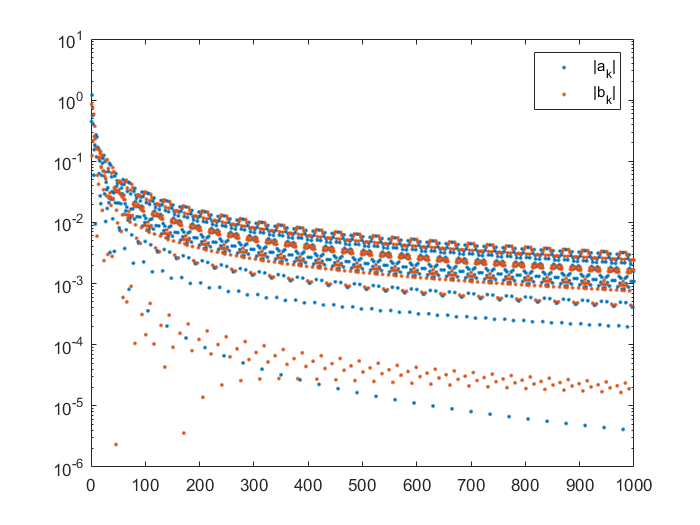

figure
semilogy(1:K, abs(a_vals), '.')
hold on;
semilogy(1:K, abs(b_vals), '.')
hold off;
legend('|a_k|', '|b_k|')

% axis([0 250 1e-6 1e1])

L2_norm = double(int(f_sym.^2, x, -k/5, k/7))

L2_norm = 2.4871

sum((a_vals/L*2).^2 + (b_vals/L*2).^2)

ans = 0.6878

## Part e

da_n = a_n * pi*n/(L/2);
db_n = b_n * pi*n/(L/2);

da_vals = zeros(K, 1);
db_vals = zeros(K, 1);
for nn = 1 : K
    da_vals(nn) = subs(da_n, n, nn);
    db_vals(nn) = subs(db_n, n, nn);
end

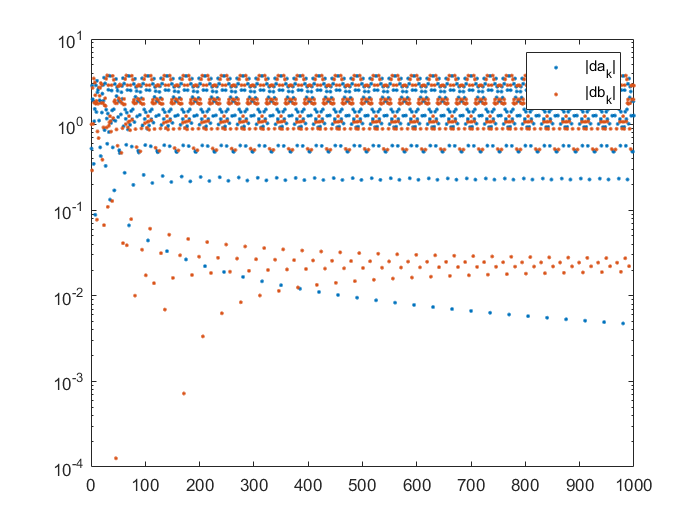

figure
semilogy(1:K, abs(da_vals), '.')
hold on;
semilogy(1:K, abs(db_vals), '.')
hold off;
legend('|da_k|', '|db_k|')

function f_val = f(x, k)
f_val = x.^2 .* (x >= -k/5 & x <= k/7);
end